v_a1 = -17:1:31;
v_a2 = 90-27:1:90+27;
withbias = false;
n_a1 = size(v_a1,2);
n_a2 = size(v_a2,2);

J11 = zeros(n_a1,n_a2);
J22 = J11;
Jmix = J11;

[mesh_a1,mesh_a2] = meshgrid(v_a1,v_a2);

for i = 1:size(v_a1,2)
    for j = 1:size(v_a2,2)
        a1 = deg2rad(v_a1(i));
        a2 = deg2rad(v_a2(j));
        
        [x, y, p1 , p2, error] = direct_kinematics(a1,a2);
        [J11(i,j), Jmix(i,j), ~, J22(i,j), error_mj] = mass_jacobian(x,y,false,withbias);
        
        

    end
end

[m11_eq, mdiag_eq, ~, m22_eq, ~] = mass_jacobian(0.127,0.127,false,withbias)       

m11_eq = 0.0017

mdiag_eq = -4.2801e-20

m22_eq = 0.0017

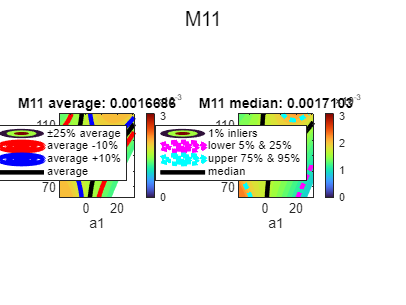


J11_v = reshape(J11,1,[]);
J22_v = reshape(J22,1,[]);
Jd_v = reshape(Jmix,1,[]);

max_J = max([J11_v J22_v]);
abs_max_Jd = max(abs(min(Jd_v)),max(Jd_v));

plotJ(J11,J11_v,mesh_a1,mesh_a2,max_J,"M11",false)

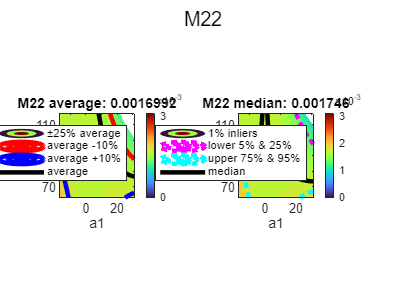

plotJ(J22,J22_v,mesh_a1,mesh_a2,max_J,"M22",false)

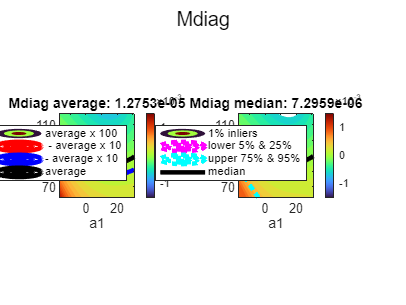

plotJ(Jmix,Jd_v,mesh_a1,mesh_a2,abs_max_Jd,"Mdiag",true)

% 
% 
% Q11 = quantile(J11_v,[0.01 0.05 0.5 0.95 0.99]);
% 
% figure;
% J11_mean = mean(J11_v);
% % J11_m_mat = J11_mean*ones(n_a1,n_a2);
% contourf(mesh_a1,mesh_a2,J11',0:0.0001:max_J,"EdgeColor","none");
% colorbar("Limits",[0 max_J])
% colormap turbo
% clim([0 max_J])
% hold on
% contour3(mesh_a1,mesh_a2,J11',[J11_mean*0.9 J11_mean],"red","LineWidth",3)
% contour3(mesh_a1,mesh_a2,J11',[ J11_mean J11_mean*1.1],"blue","LineWidth",3)
% contour3(mesh_a1,mesh_a2,J11',Q11(2:3),":magenta","LineWidth",2)
% contour3(mesh_a1,mesh_a2,J11',Q11(3:4),":cyan","LineWidth",2)
% contour3(mesh_a1,mesh_a2,J11',[ J11_mean J11_mean ],"black","LineWidth",3)
% contour3(mesh_a1,mesh_a2,J11',[ Q11(3) Q11(3)  ],":white","LineWidth",3)
% % contour3(mesh_a1,mesh_a2,J11',[Q11(1) Q11(2)],"red",'ShowText','on')
% % contour3(mesh_a1,mesh_a2,J11',[ Q11(4) Q11(5)],"blue",'ShowText','on')
% % contour3(mesh_a1,mesh_a2,J11',[ Q11(3) Q11(3) ],"black",'ShowText','on')
% hold off
% title("M11 average: "+J11_mean);
% xlabel("a1")
% ylabel("a2")
% zlabel("Kg m2")
% zlim([0 1.2*max(J11_v)])
% daspect([1 1 0.0004])
% view([0 90.0000])
% legend(["J11", "average -10%","average +10%" ,"average"])
% % legend(["J11", "lower 2.5% & 25%","upper 2.5% & 25%" ,"mean"])
% 
% 
% figure;
% J22_mean = mean(J22_v);
% contourf(mesh_a1,mesh_a2,J22',0:0.0001:max_J,"EdgeColor","none");
% colorbar("Limits",[0 max_J])
% clim([0 max_J])
% colormap turbo
% hold on
% contour3(mesh_a1,mesh_a2,J22',[J22_mean*0.9 J22_mean ],"red","LineWidth",3)
% contour3(mesh_a1,mesh_a2,J22',[J22_mean J22_mean*1.1 ],"blue","LineWidth",3)
% contour3(mesh_a1,mesh_a2,J22',[ J22_mean J22_mean],"black","LineWidth",2)
% hold off
% title("M22 average: "+J22_mean);
% xlabel("a1")
% ylabel("a2")
% zlabel("Kg m2")
% zlim([0 1.2*max(J22_v)])
% daspect([1 1 0.0004])
% view([0 90.0000])
% legend(["J22", "average -10%","average +10%" ,"average"])
% 
% 
% 
% abs_max_Jd = max(abs(min(Jd_v)),max(Jd_v));
% 
% figure;
% 
% surf(mesh_a1,mesh_a2,Jmix',"EdgeColor","none");
% colorbar("Limits",[-abs_max_Jd abs_max_Jd])
% colormap turbo
% clim([-abs_max_Jd abs_max_Jd])
% hold on
% contour3(mesh_a1,mesh_a2,Jmix',[Jd_mean*0.9 Jd_mean*1.1 ],"red")
% hold off
% title("M12/21 average: "+Jd_mean);
% xlabel("a1")
% ylabel("a2")
% zlabel("Kg m2")
% zlim([ -1.2*abs_max_Jd 1.2*abs_max_Jd])
% daspect([1 1 0.0004])
% view([0 90.0000])
% legend(["Jd", "average ±10%"])


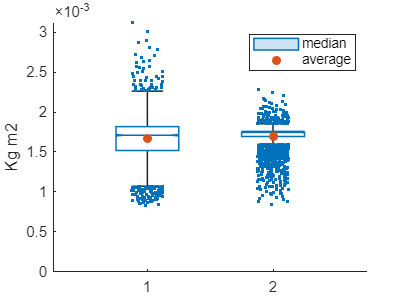

J11_mean = mean(J11_v);
J22_mean = mean(J22_v);
figure
x_chart = categorical(["M11" "M22"]);
y_chart = [J11_v' , J22_v' ];
b=boxchart(y_chart,'Notch','on');
hold on
scatter([1 2],[J11_mean J22_mean],"filled")
hold off
legend(["median","average"])
b.JitterOutliers = 'on';
b.MarkerStyle = '.';
ylabel("Kg m2")
ylim([0 max_J])


cov(J11_v)

ans = 8.4486e-08

cov(J22_v)

ans = 2.3940e-08

function plotJ(values,v_values,mesh_a1,mesh_a2,max_ax,plot_title, equi)

if equi
    min_ax = -max_ax;
else 
    min_ax = 0;
end
q = quantile(v_values,[0.01 0.05 0.5 0.95 0.99]);

v_mean = mean(v_values);
figure;
subplot(1,2,1)
sgtitle(plot_title)
% J11_m_mat = J11_mean*ones(n_a1,n_a2);
if equi
    contourf(mesh_a1,mesh_a2,values',-100*abs(v_mean):0.0001:100*abs(v_mean),"EdgeColor","none",'ShowText','on');
    hold on
    contour3(mesh_a1,mesh_a2,values',[-abs(v_mean)*10 abs(v_mean)],"red","LineWidth",3)
    contour3(mesh_a1,mesh_a2,values',[ abs(v_mean) abs(v_mean)*10],"blue","LineWidth",3)
    contour3(mesh_a1,mesh_a2,values',[ -abs(v_mean) abs(v_mean) ],"black","LineWidth",3)
else 
    contourf(mesh_a1,mesh_a2,values',0.75*v_mean:0.0001:1.25*v_mean,"EdgeColor","none",'ShowText','on');
    hold on
    contour3(mesh_a1,mesh_a2,values',[v_mean*0.9 v_mean],"red","LineWidth",3)
    contour3(mesh_a1,mesh_a2,values',[ v_mean v_mean*1.1],"blue","LineWidth",3)
    contour3(mesh_a1,mesh_a2,values',[ v_mean v_mean ],"black","LineWidth",3)

end
colorbar("Limits",[min_ax max_ax])
colormap turbo
clim([min_ax max_ax])
% contour3(mesh_a1,mesh_a2,J11',[Q11(1) Q11(2)],"red",'ShowText','on')
% contour3(mesh_a1,mesh_a2,J11',[ Q11(4) Q11(5)],"blue",'ShowText','on')
% contour3(mesh_a1,mesh_a2,J11',[ Q11(3) Q11(3) ],"black",'ShowText','on')
hold off
title(plot_title+" average: "+v_mean);
xlabel("a1")
ylabel("a2")
zlabel("Kg m2")
zlim([0 1.2*max_ax])
daspect([1 1 0.0004])
view([0 90.0000])
if equi
    legend(["average x 100", " - average x 10","- average x 10" ,"average"])
else 
    legend(["±25% average", "average -10%","average +10%" ,"average"])
end
% legend(["J11", "lower 2.5% & 25%","upper 2.5% & 25%" ,"mean"])


subplot(1,2,2)
contourf(mesh_a1,mesh_a2,values',q(1):0.0001:q(5),"EdgeColor","none",'ShowText','on');
colorbar("Limits",[min_ax max_ax])
colormap turbo
clim([min_ax max_ax])
hold on
contour3(mesh_a1,mesh_a2,values',q(2:3),":magenta","LineWidth",3)
contour3(mesh_a1,mesh_a2,values',q(3:4),":cyan","LineWidth",3)
contour3(mesh_a1,mesh_a2,values',[ q(3) q(3)  ],"black","LineWidth",3)
hold off
title(plot_title+" median: "+q(3));
xlabel("a1")
ylabel("a2")
zlabel("Kg m2")
zlim([0 1.2*max_ax])
daspect([1 1 0.0004])
view([0 90.0000])
legend(["1% inliers", "lower 5% & 25%","upper 75% & 95%" ,"median"])
end

